This program uses file lab1.xlsx

% a. Import data
% Use the "Import Data" tab
% Select column A to L, row 2 to 210


Data on CEO `Salary. `

Variable list

     1. salary                   1990 salary, thousands $ 

     2. pcsalary                 % change salary, 89-90 

     3. sales                    1990 firm sales, millions $ 

     4. roe                      return on equity, 88-90 avg 

     5. pcroe                    % change roe, 88-90 

     6. ros                      return on firm's stock, 88-90 

     7. indus                    =1 if industrial firm   

     8. finance                  =1 if financial firm   

     9. consprod                 =1 if consumer product firm 

    10. utility                  =1 if transport. or utilties 

    11. lsalary                  natural log of salary   

    12. lsales                   natural log of sales   

     6. ros                      return on firm's stock, 88-90 

     7. indus                    =1 if industrial firm   

     8. finance                  =1 if financial firm   

     9. consprod                 =1 if consumer product firm 

    10. utility                  =1 if transport. or utilties 

    11. lsalary                  natural log of salary   

    12. lsales                   natural log of sales   

We focus on the determinats of CEO salaries

% assign variable names

salary = lab1{ : ,1};
pcsalary = lab1{ : ,2};
sales = lab1{ : ,3};
roe = lab1{ : ,4};
pcroe = lab1{ : ,5};
ros = lab1{ : ,6};
indus = lab1{ : ,7};
finance = lab1{ : ,8}

finance =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


consprod = lab1{ : ,9}

consprod =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


utility = lab1{ : ,10}

utility =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


lsalary = lab1{ : ,11}

lsalary =     6.9088
    7.0229
    6.3596
    7.2211
    7.0432
    6.9829
    6.9976
    7.1204
    6.7250
    6.3404


lsales = lab1{ : ,12}

lsales =     9.2061
    8.7203
    9.6956
    9.9889
    8.7031
    7.7261
    7.9952
    8.4273
    7.9480
    6.3916


% b. Basic statistics of variables
%summary(lab1CEO)

% imput dataset in matrix lab
lab = lab1{:,:};



- Let's compute the correlation matrix of the first 6 variables

The first row denotes the correlation of salary with the other 5 variables 

  1. salary                   1990 salary, thousands $ 

     2. pcsalary                 % change salary, 89-90 

     3. sales                    1990 firm sales, millions $ 

     4. roe                      return on equity, 88-90 avg 

     5. pcroe                    % change roe, 88-90 

     6. ros                      return on firm's stock, 88-90 

% correlationn matrix of the first six variables
corrcoef(lab(:,1:6))

ans =     1.0000    0.0088    0.1223    0.1146    0.0294   -0.0327
    0.0088    1.0000    0.0152    0.0877    0.2075    0.1371
    0.1223    0.0152    1.0000   -0.0525   -0.0037   -0.1567
    0.1146    0.0877   -0.0525    1.0000    0.0059    0.2808
    0.0294    0.2075   -0.0037    0.0059    1.0000    0.1213
   -0.0327    0.1371   -0.1567    0.2808    0.1213    1.0000


2.   Which two variables exhibit the highest correlation with salary?

3.   Are these two variables highly correlated? 

corrcoef(sales,roe)

ans =     1.0000   -0.0525
   -0.0525    1.0000


Our candidate measures of  firm performance to relate to salary are sales and roe.

Before proceeding, let's visualize the empirical distribution of salary, sales, and roe  with histograms

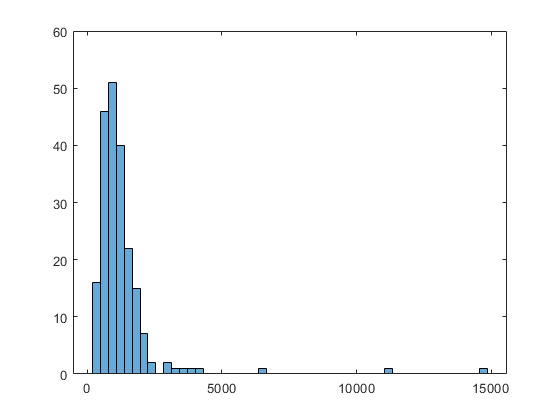

histsalary =   Histogram with properties:

             Data: [208×1 double]
           Values: [16 46 51 40 22 15 7 2 0 2 1 1 1 1 0 0 0 0 0 0 0 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 1 0 0 0 0 0 0 0 0 0 0 0 1]
          NumBins: 50
         BinEdges: [1×51 double]
         BinWidth: 293
        BinLimits: [200 14850]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


histsalary = histogram(salary, 50)

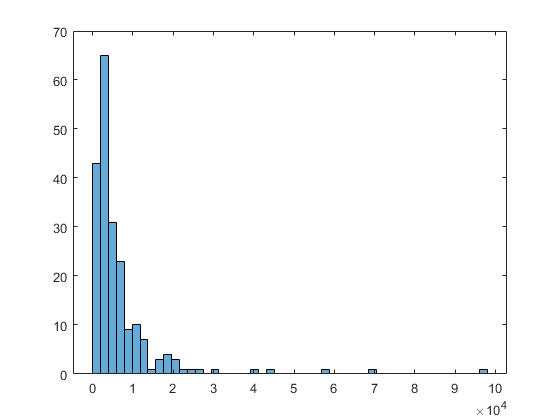

histsales =   Histogram with properties:

             Data: [208×1 double]
           Values: [43 65 31 23 9 10 7 1 3 4 3 1 1 1 0 1 0 0 0 0 1 0 1 0 0 0 0 0 0 1 0 0 0 0 0 1 0 0 0 0 0 0 0 0 0 0 0 0 0 1]
          NumBins: 50
         BinEdges: [1×51 double]
         BinWidth: 1960
        BinLimits: [0 98000]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


histsales = histogram(sales, 50)

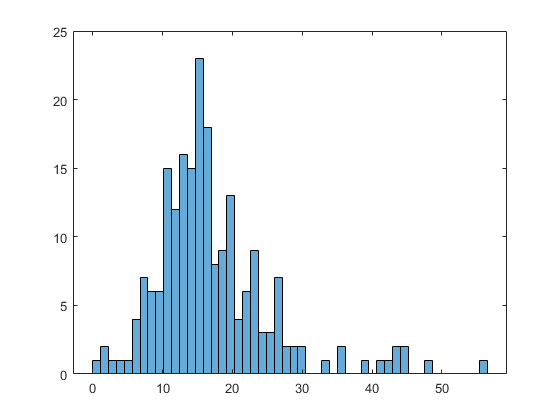

histroe =   Histogram with properties:

             Data: [208×1 double]
           Values: [1 2 1 1 1 4 7 6 6 15 12 16 15 23 18 8 9 13 4 6 9 3 3 7 2 2 2 0 0 1 0 2 0 0 1 0 1 1 2 2 0 0 1 0 0 0 0 0 0 1]
          NumBins: 50
         BinEdges: [1×51 double]
         BinWidth: 1.1300
        BinLimits: [0 56.5000]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


histroe = histogram(roe, 50)

4.   Comment on the results

Let's now look first at a scatter plot of salary (y axis)  and  sales (x axis)

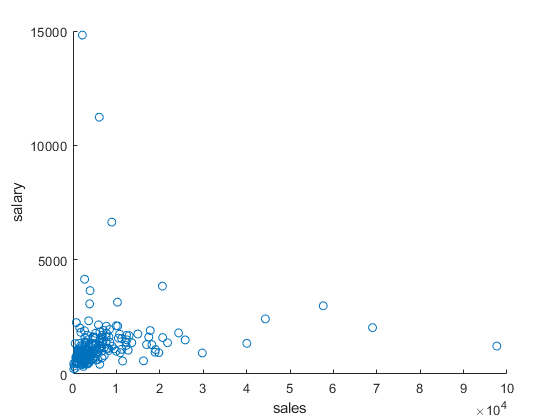

scatter (sales,salary)
xlabel('sales')
ylabel('salary')

5. Would you expect to find a linear relationship between these two variables?

Let's now look at a scatter plot of salary (y axis)  and  roe (x axis)

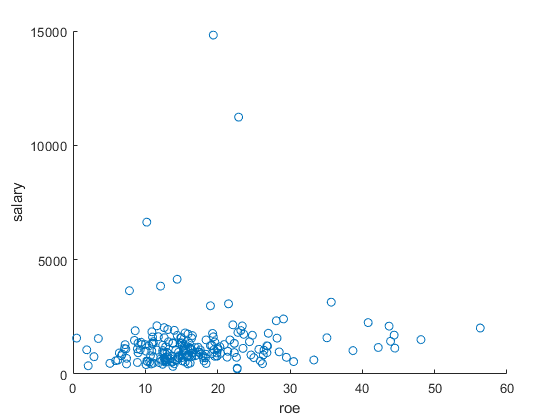

scatter (roe,salary)
xlabel('roe')
ylabel('salary')

6. Would you expect to find a linear relationship between these two variables?

Let's estimate a simple univariate regression with salary and roe, and plot the results

% help fitlm 
x = table(salary,roe);
lm =fitlm(x,'salary ~ roe')

lm = Linear regression model:
    salary ~ 1 + roe

Estimated Coefficients:
                   Estimate      SE      tStat       pValue  
                   ________    ______    ______    __________

    (Intercept)     964.27     214.06    4.5047    1.1125e-05
    roe             18.475     11.154    1.6564      0.099163


Number of observations: 208, Error degrees of freedom: 206
Root Mean Squared Error: 1.37e+03
R-squared: 0.0131,  Adjusted R-Squared: 0.00835
F-statistic vs. constant model: 2.74, p-value = 0.0992

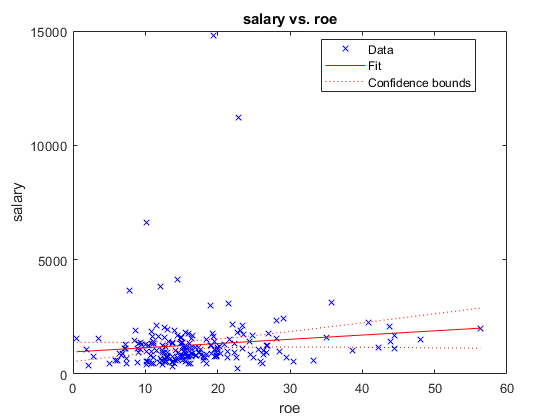

plot(lm)

7. Comment the results

Now, let's estimate a regression with salary and sales

%help fitml
x = table(salary,sales);
lm =fitlm(x,'salary ~ sales')

lm = Linear regression model:
    salary ~ 1 + sales

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    _________    ______    __________

    (Intercept)      1173.3       113.06    10.378    1.4467e-20
    sales          0.015926    0.0090069    1.7682      0.078513


Number of observations: 208, Error degrees of freedom: 206
Root Mean Squared Error: 1.37e+03
R-squared: 0.0149,  Adjusted R-Squared: 0.0102
F-statistic vs. constant model: 3.13, p-value = 0.0785

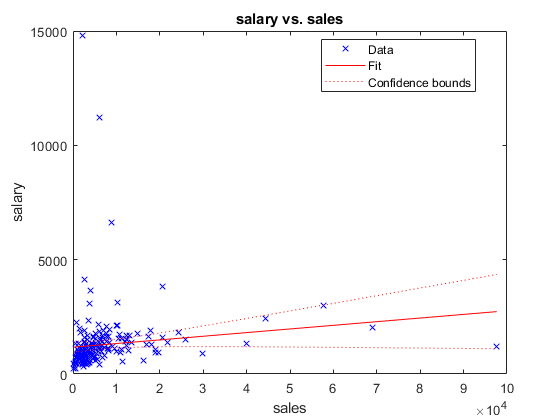

plot(lm)

7. Comment the results, and compare them with the previous regression

Are there non-linearities in the data?

Let' now consider to incorporate non-linearities 

Let's run a regression with logsalary and logsales as a predictor

logsalary = log(salary);
logsales = log(sales);
x = table(logsalary,logsales);
lm =fitlm(x,'logsalary ~ logsales')

lm = Linear regression model:
    logsalary ~ 1 + logsales

Estimated Coefficients:
                   Estimate       SE       tStat       pValue  
                   ________    ________    ______    __________

    (Intercept)     4.7898       0.2907    16.477    1.8221e-39
    logsales       0.26082     0.034841    7.4861     2.033e-12


Number of observations: 208, Error degrees of freedom: 206
Root Mean Squared Error: 0.505
R-squared: 0.214,  Adjusted R-Squared: 0.21
F-statistic vs. constant model: 56, p-value = 2.03e-12

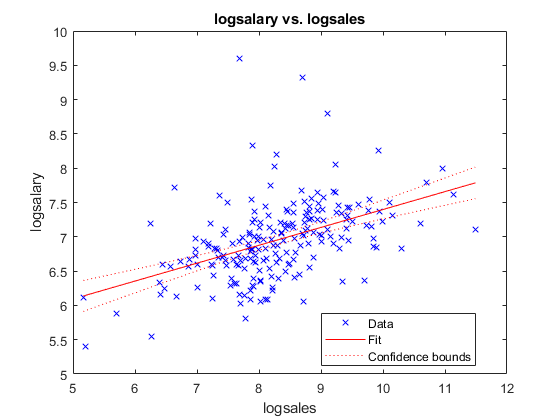

plot(lm)

8. Comment the results, and compare with the previous level regression

Finally, as a preview of incoming exercises, we noticed sales and roe have a positive correlation with salary, but their correlation is small. 

Let's see a scatter plot of sales and roe

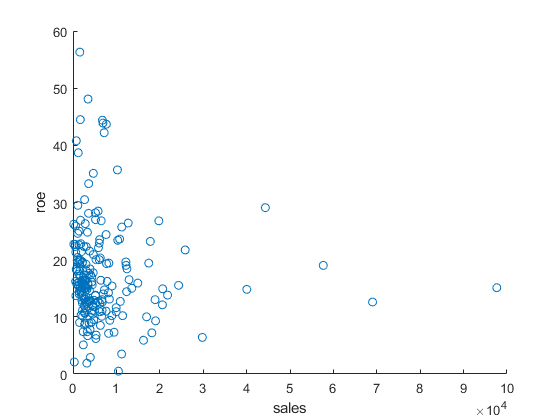

scatter(sales,roe)
xlabel('sales')
ylabel('roe')

Could a regression with both sales and roe improve the fit of the original one variable regressions?

Let's check this multivariate regression 

x1 = table(sales,roe,salary);
lm =fitlm(x1,'salary ~ sales + roe')

lm = Linear regression model:
    salary ~ 1 + sales + roe

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    _________    ______    __________

    (Intercept)      831.21       224.39    3.7043    0.00027261
    sales          0.016756    0.0089736    1.8672        0.0633
    roe              19.563       11.102    1.7621      0.079548


Number of observations: 208, Error degrees of freedom: 205
Root Mean Squared Error: 1.36e+03
R-squared: 0.0296,  Adjusted R-Squared: 0.0202
F-statistic vs. constant model: 3.13, p-value = 0.0457

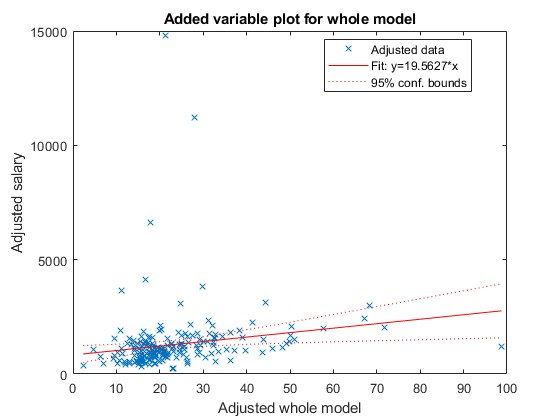

plot(lm)